%To get the sampling rate and the data of the two channels
[signal1,Fs1]= audioread('Short_QuranPalestine.wav')

signal1 =    1.0e-04 *

         0         0
   -0.3052         0
         0         0
         0   -0.3052
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Fs1 = 44100

[signal2,Fs2]= audioread('Short_FM9090.wav')

signal2 =    1.0e-04 *

         0         0
   -0.3052         0
         0         0
         0   -0.3052
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Fs2 = 44100

% making the signal have only one channel
One_channelsignal1=(signal1(:,1)+signal1(:,2))

One_channelsignal1 =    1.0e-04 *

         0
   -0.3052
         0
   -0.3052
         0
         0
         0
         0
         0
         0


One_channelsignal2=(signal2(:,1)+signal2(:,2))

One_channelsignal2 =    1.0e-04 *

         0
   -0.3052
         0
   -0.3052
         0
         0
         0
         0
         0
         0


% Making the two signals have the same Length

X1=length(One_channelsignal1) %The First length of signal 1 before Padding

X1 = 739200

X2=length(One_channelsignal2) %The First length of signal 2 before Padding

X2 = 697536


One_channelsignal2(length(One_channelsignal2):length(One_channelsignal1))=0;
%One_channelsignal1=One_channelsignal1(1:length(One_channelsignal1)/4) ;
%One_channelsignal2=One_channelsignal2(1:length(One_channelsignal2)/4) ;
a=length(One_channelsignal1) % to know the length of signal 1

a = 739200

b=length(One_channelsignal2) % to know the length of signal 2

b = 739200

% to get the spectrum of unmodulated signal 1
Y1=fft(One_channelsignal1);
length(Y1)

ans = 739200

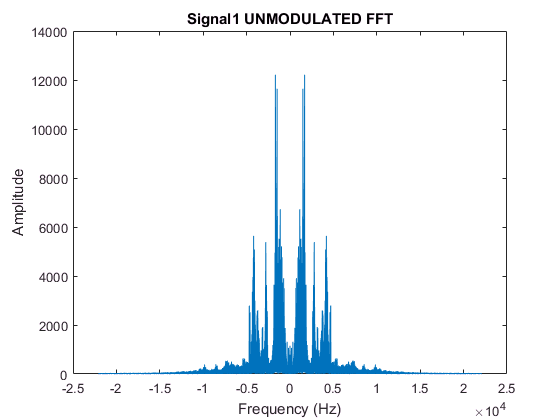


N=a;
k=-N/2:N/2-1;

%subplot(3,2,1)
plot(k*Fs1/N,fftshift(abs(Y1)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Signal1 UNMODULATED FFT')

%%%%%%%%%%%%%%%% to get the spectrum of unmodulated signal 2 %%%%%%%%%%%%%%%%%%%%%
Y2=fft(One_channelsignal2);
length(Y2)

ans = 739200

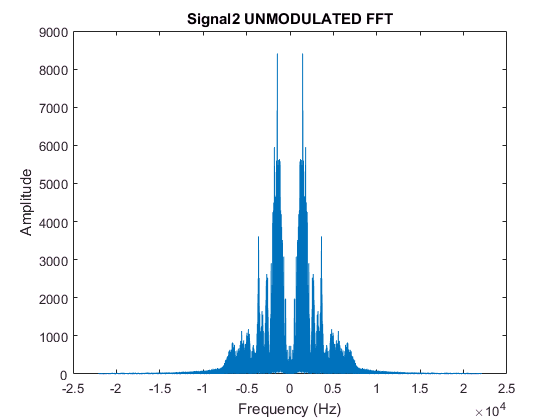



N=a;
k=-N/2:N/2-1;
%subplot(3,2,2)

plot(k*Fs1/N,fftshift(abs(Y2)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Signal2 UNMODULATED FFT')

% To increase the sample rate of signal 1
sig1=interp(One_channelsignal1,10) %signal1 after interpolation where 10 is the interpolation factor  

sig1 =    1.0e-04 *

         0
   -0.0558
   -0.1098
   -0.1601
   -0.2053
   -0.2438
   -0.2743
   -0.2961
   -0.3086
   -0.3116


L1i=length(sig1) % The new length after increasing the samples rate of signal 1  

L1i = 7392000

k1i=-L1i/2:L1i/2-1;
% To increase the sample rate of signal 2
sig2=interp(One_channelsignal2,10) %signal2 after interpolation where 10 is the interpolation factor

sig2 =    1.0e-04 *

         0
   -0.0558
   -0.1098
   -0.1601
   -0.2053
   -0.2438
   -0.2743
   -0.2961
   -0.3086
   -0.3116


L2i=length(sig1) % The new length after increasing the samples rate of signal 2 

L2i = 7392000

k2i=-L2i/2:L2i/2-1;
%The AM modulator:
%1-Generation of a cosine signal in discrete time domain
Ts_new=1/(10*Fs1); 
w1=2*pi*100000 % the freq of the first signal

w1 = 6.2832e+05

w2=2*pi*150000 %the freq of the second signal from the eqn (100k+n*50k)

w2 = 9.4248e+05

n=k2i ;
Carrier1=(cos(w1*n*Ts_new))';  %The carrier of the first signal
Carrier2=(cos(w2*n*Ts_new))'; %The carrier of the second signal
Mod_sig1=sig1.*Carrier1;
Mod_sig2=sig2.*Carrier2;
Transmitted_signal=Mod_sig1+Mod_sig2

Transmitted_signal =    1.0e-04 *

         0
   -0.0002
   -0.0723
    0.0667
    0.3053
   -0.3284
   -0.3081
    0.4657
    0.0716
   -0.1900


%Plotting modulated signal 1
Y2=fft(Mod_sig1);
M=length(Y2)

M = 7392000

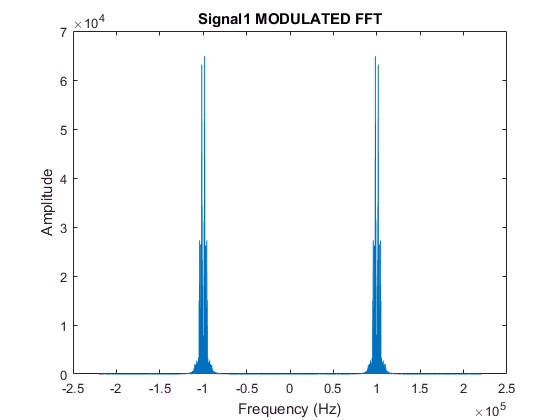

N=M;
k=-N/2:N/2-1;

%subplot(3,2,3)
plot(k*10*Fs1/N,fftshift(abs(Y2)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Signal1 MODULATED FFT')

%Plotting modulated signal 2
Y2=fft(Mod_sig2);
M=length(Y2)

M = 7392000

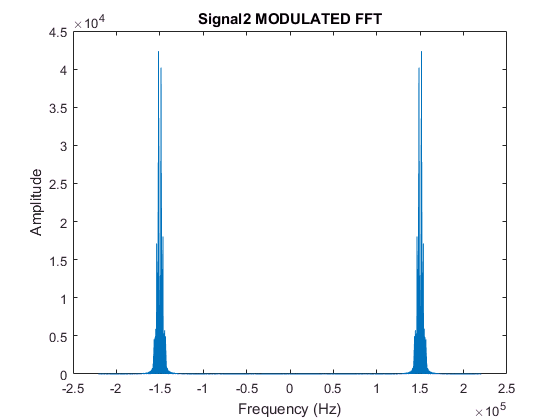

N=M;
k=-N/2:N/2-1;
%subplot(3,2,4)
plot(k*10*Fs1/N,fftshift(abs(Y2)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Signal2 MODULATED FFT')

%Plotting the transmitted signal 
Y2=fft(Transmitted_signal);
M=length(Y2)

M = 7392000

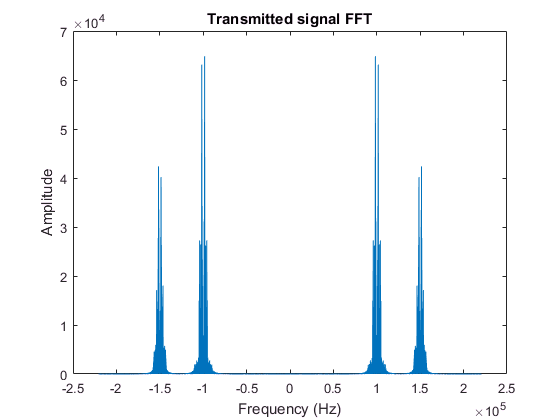

N=M;
k=-N/2:N/2-1;
%subplot(3,2,5)
plot(k*10*Fs1/N,fftshift(abs(Y2)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Transmitted signal FFT')

% The RF stage (The design of Bandpass filter)

RFBW=2*0.5*10^4; %2*BBBW WHERE BBBW=0.5*10^4
F_stop1=60000; 
F_stop2=140000; 
F_pass1=95000; 
F_pass2=105000 

F_pass2 = 105000

RF_Filter =fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2',F_stop1, F_pass1, F_pass2, F_stop2,60,1,60,441000);
RF_info= design(RF_Filter, 'butter');  %This function used to determine the type of the filter and the specs of the filter and i chose the Butterworth filter because of its maximum pass-band flatness 
RF_Filter_OUT=filter(RF_info,Transmitted_signal); %this function filters the transmitted signal after giving it the full info about RF filter
Y3=fft(RF_Filter_OUT); 
M=length(Y3)

M = 7392000

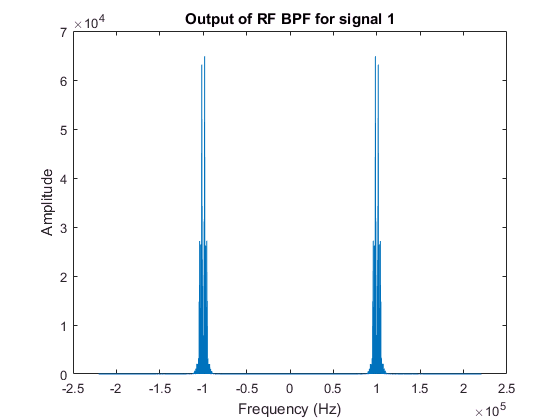

N=M;
k=-N/2:N/2-1;
%subplot(3,2,6)

plot(k*10*Fs1/N,fftshift(abs(Y3)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Output of RF BPF for signal 1')

%%%%%%%%%%%%%%%%%%%%%%%%%%Mixer stage %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
W_IF=2*pi*25*10^3;
Wc=2*pi*100000;
Oscillator_carrier=cos(((Wc+W_IF)*n*Ts_new))'

Oscillator_carrier =     0.9556
    0.0889
   -0.9927
    0.3252
    0.8570
   -0.6828
   -0.5721
    0.9215
    0.1877
   -0.9998


mixer_output=Oscillator_carrier.*RF_Filter_OUT;
Y3=fft(mixer_output); 
M=length(Y3)

M = 7392000

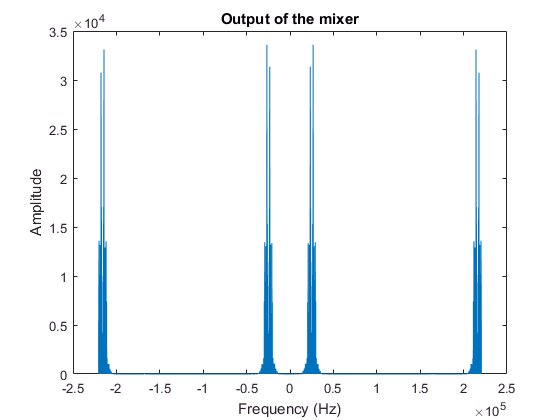

N=M;
k=-N/2:N/2-1;
%subplot(4,2,6)
figure;
plot(k*10*Fs1/N,fftshift(abs(Y3)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Output of the mixer')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% IF_stage %%%%%%%%%%%%%%%%%%%%%%%
RFBW=2*0.5*10^4; %2*BBBW WHERE BBBW=0.5*10^4
F_stop1=9000; 
F_stop2=49000; 
F_pass1=15000; 
F_pass2=35000 

F_pass2 = 35000

RF_Filter =fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2',F_stop1, F_pass1, F_pass2, F_stop2,60,1,60,441000);
RF_info= design(RF_Filter, 'butter');  %This function used to determine the type of the filter and the specs of the filter and i chose the Butterworth filter because of its maximum pass-band flatness 
RF_Filter_OUT=filter(RF_info,mixer_output); %this function filters the transmitted signal after giving it the full info about RF filter
Y3=fft(RF_Filter_OUT); 
M=length(Y3)

M = 7392000

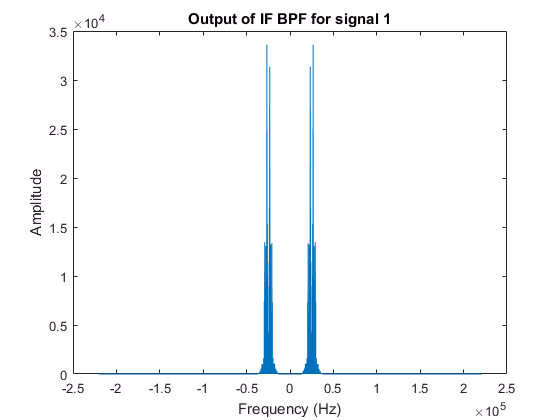

N=M;
k=-N/2:N/2-1;
%subplot(3,2,6)
%figure(2)
plot(k*10*Fs1/N,fftshift(abs(Y3)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Output of IF BPF for signal 1')

%%%%%%%%%%%%%%%%%%%%%%% Final stage: Base Band stage%%%%%%%%%%%%%%%%%%%
Carrier_Baseband_Transpose=cos(2*pi*25*10^3*n*Ts_new)';
signal_before_LPF=RF_Filter_OUT.*Carrier_Baseband_Transpose

signal_before_LPF =    1.0e-14 *

         0
   -0.0000
   -0.0000
   -0.0001
   -0.0010
   -0.0084
   -0.0461
   -0.1805
   -0.4974
   -0.8072


Y3=fft(signal_before_LPF); 
M=length(Y3)

M = 7392000

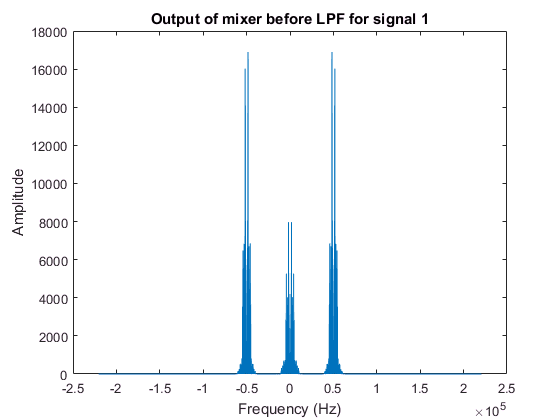

N=M;
k=-N/2:N/2-1;
plot(k*10*Fs1/N,fftshift(abs(Y3)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Output of mixer before LPF for signal 1')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% LPF %%%%%%%%%%%%%%% 
LPF = fdesign.lowpass('Fp,Fst,Ap,Ast',25000,45000,1,60,441000);
LPF_info= design(LPF, 'butter');  %This function used to determine the type of the filter and the specs of the filter and i chose the Butterworth filter because of its maximum pass-band flatness 
LPF_Filter_OUT=filter(LPF_info,signal_before_LPF); %this function filters the signal before LPF after giving it the full info about LPF filter
Y3=fft(LPF_Filter_OUT); 
M=length(Y3)

M = 7392000

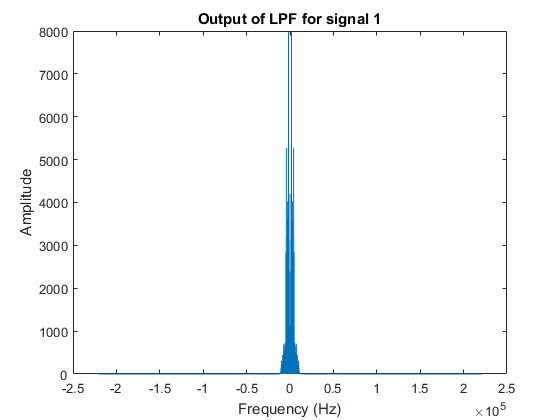

N=M;
k=-N/2:N/2-1;
plot(k*10*Fs1/N,fftshift(abs(Y3)))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Output of LPF for signal 1')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Down_sampling %%%%%%%%%%%%%%%%%%%%%
Y=downsample(LPF_Filter_OUT,10);
sound(Y,44100)